clear; close all;

%% Parameters
%
% Make a zero vector of Zernike coefficients to
% represent a diffraction limited pupil function,
% and a few other things.
pupilDiameterMm = 6;
wave = (400:10:740)';
accommodatedWavelength = 530;
zCoeffs = zeros(66,1);

%% Set up wavefront optics object
%
% Compute pupil function using 'no lca' key/value pair to turn off LCA.
% You can turn it back on to compare the effect.
wvfP = wvfCreate('calc wavelengths', wave, 'zcoeffs', zCoeffs, ...
    'name', sprintf('human-%d', pupilDiameterMm));
wvfP = wvfSet(wvfP, 'measured pupil size', pupilDiameterMm);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMm);

% Deal with best focus by specifying that the wavefront parameters
% were measured at the wavelength we want to say is in focus. This
% is a little bit of a hack but seems OK for the diffraction limited case
% we're using here.
wvfP = wvfSet(wvfP, 'measured wavelength', accommodatedWavelength);

%% Make optical image object using wvfP and no LCA calc
%
% Same as above but don't defeat LCA calc
wvfPNoLca = wvfComputePupilFunction(wvfP,false,'no lca',true);
wvfPNoLca = wvfComputePSF(wvfPNoLca);
theOINoLca = wvf2oi(wvfPNoLca);
opticsNoLca = oiGet(theOINoLca, 'optics');
opticsNoLca = opticsSet(opticsNoLca, 'model', 'shift invariant');
opticsNoLca = opticsSet(opticsNoLca, 'name', 'human-wvf-nolca');
theOINoLca = oiSet(theOINoLca,'optics',opticsNoLca);

%% For comparison, make optical image object using wvfP with LCA calc
wvfPWithLca = wvfComputePupilFunction(wvfP,false,'no lca',false);
wvfPWithLca = wvfComputePSF(wvfPWithLca);
theOIWithLca = wvf2oi(wvfPWithLca);
opticsWithLca = oiGet(theOIWithLca, 'optics');
opticsWithLca = opticsSet(opticsWithLca, 'model', 'shift invariant');
opticsWithLca = opticsSet(opticsWithLca, 'name', 'human-wvf-withlca');
theOIWithLca = oiSet(theOIWithLca,'optics',opticsWithLca);
% theOIWithLca = oiCreate('wvf human');

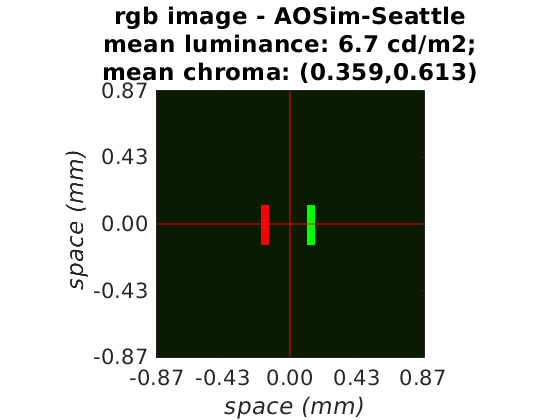

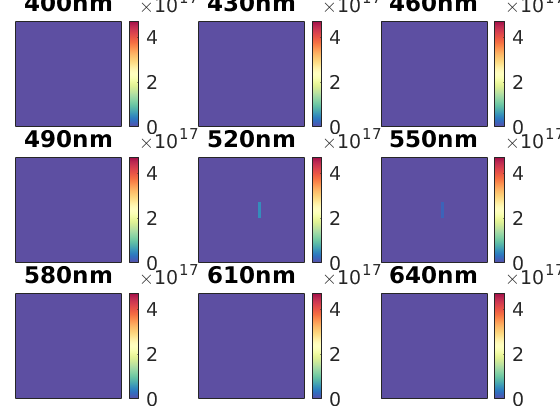

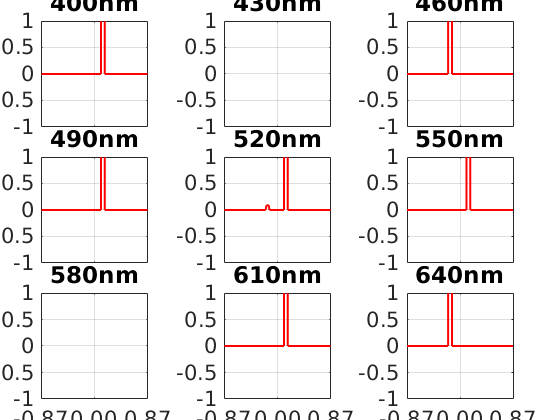

%% Create the scene
presentationDisplay = displayCreate('AOSim-Seattle');
% scene = generateTwoLineScene(presentationDisplay,1,20);
% scene = generateGaborSceneAO(presentationDisplay); 
scene = generateTwoLineScene(presentationDisplay,1,20);
visualizeScene(scene, 'displayContrastProfiles', true); 

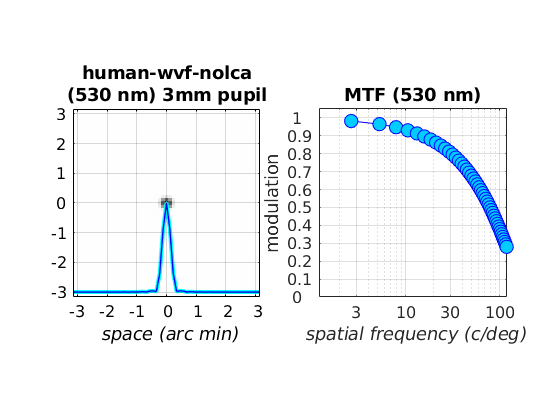

%% Compute and visualize the retinal images with and without LCA
theOINoLca = oiCompute(theOINoLca, scene);
% Visualize the PSFs and OTFs
visualizedSpatialSupportArcMin = 6;
visualizedSpatialSfrequencyCPD = 120;
% Visualize the PSF/OTF at 530 (in-focus)
visualizeOptics(theOINoLca, 530, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);

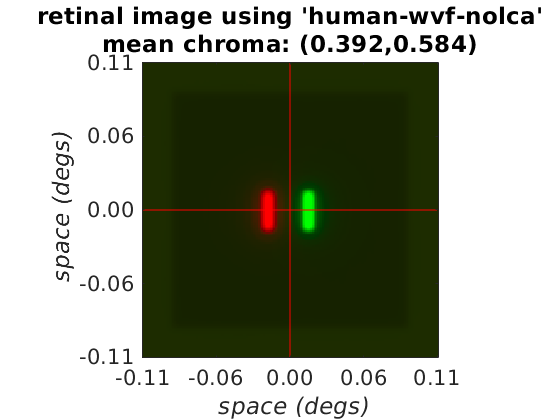

% Visualize the optical image as an RGB image and a few spectral slices
visualizeOpticalImage(theOINoLca, 'displayRadianceMaps', false, ...
    'displayRetinalContrastProfiles', false);

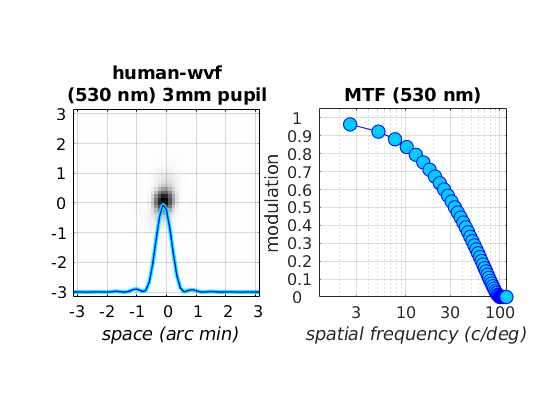

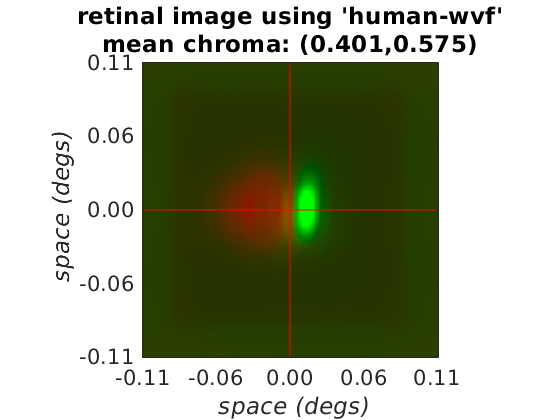

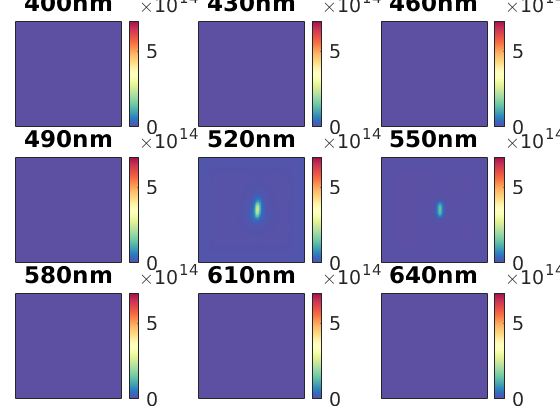

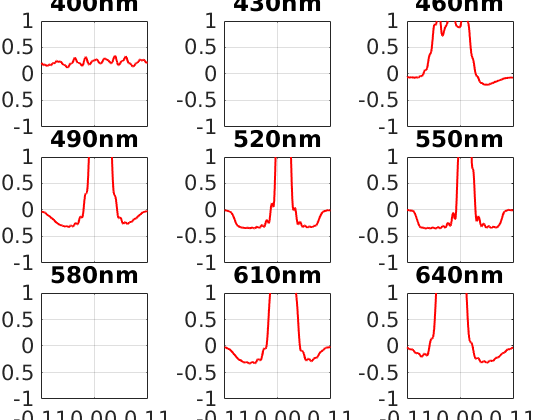

%% Compute and visualize the retinal images with and without LCA
theOIWithLca = oiCompute(theOIWithLca, scene);
% Visualize the PSFs and OTFs
visualizedSpatialSupportArcMin = 6;
visualizedSpatialSfrequencyCPD = 120;
% Visualize the PSF/OTF at 530 (in-focus)
visualizeOptics(theOIWithLca, 530, visualizedSpatialSupportArcMin, visualizedSpatialSfrequencyCPD);
% Visualize the optical image as an RGB image and a few spectral slices
visualizeOpticalImage(theOIWithLca, 'displayRadianceMaps', true, ...
    'displayRetinalContrastProfiles', true);

Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 105.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.568029, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 105.00 116.36 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 1.047741, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 0.00 105.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.322350, Tolerange: 0.001000
Number of Delaunay triangulations: 10
[PASS:  2/ 3]. Adjusting cones between 105.00 116.36 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.985121, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  2/ 3]. Adjusting cones between 0.00 105.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.251410, Tolerange: 0.001000
Number of Delaunay triangulations: 9
[PASS:  3/ 3]. Adjusting cones between 105.00 116.36 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.957454, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  3/ 3]. Adjusting cones between 0.00 105.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 

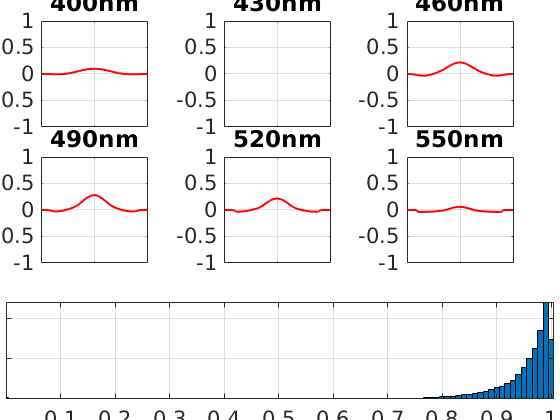


Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.172941, Tolerange: 0.001000
Number of Delaunay triangulations: 8

Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 406
Scones after making an S-cone free central patch: 264 (added Lcones:94, added Mcones:48)
Scones after pass 1: 161 (added Lcones:90, added Mcones:45)
Scones after pass 2: 123 (added Lcones:31, added Mcones:18)
Scones after pass 3: 114 (added Lcones:8, added Mcones:4

%% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...               % hex lattice sampling factor
   'fovDegs', sceneGet(scene, 'fov'), ... % match mosaic width to stimulus size
   'eccBasedConeDensity', true, ...            % cone density varies with eccentricity
   'eccBasedConeQuantalEfficiency', true, ...  % cone quantal efficiency varies with eccentricity
   'integrationTime', 30/1000, ...             % 30 msec integration time
   'maxGridAdjustmentIterations', 50);         % terminate iterative lattice adjustment after 50 iterations

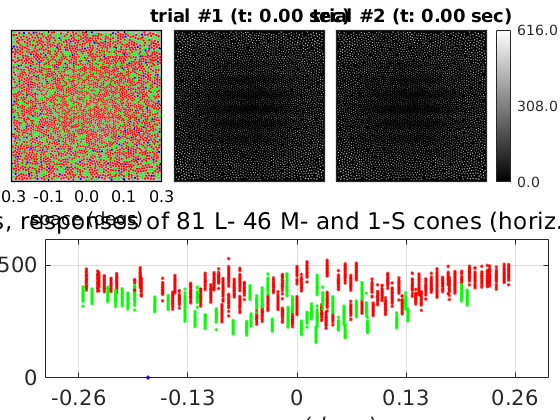

%% Compute some instances of cone mosaic excitations
nInstancesNum = 32;
% Zero fixational eye movements
emPath = zeros(nInstancesNum, 1, 2);
% Compute mosaic excitation responses
% coneExcitations = theMosaic.compute(theOINoLca, 'emPath', emPath);
coneExcitations = theMosaic.compute(theOIWithLca, 'emPath', emPath);

% Compute the mean response across all instances
meanConeExcitation = mean(coneExcitations,1);
visualizeConeMosaicResponses(theMosaic, coneExcitations, 'R*/cone/tau');